plt =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


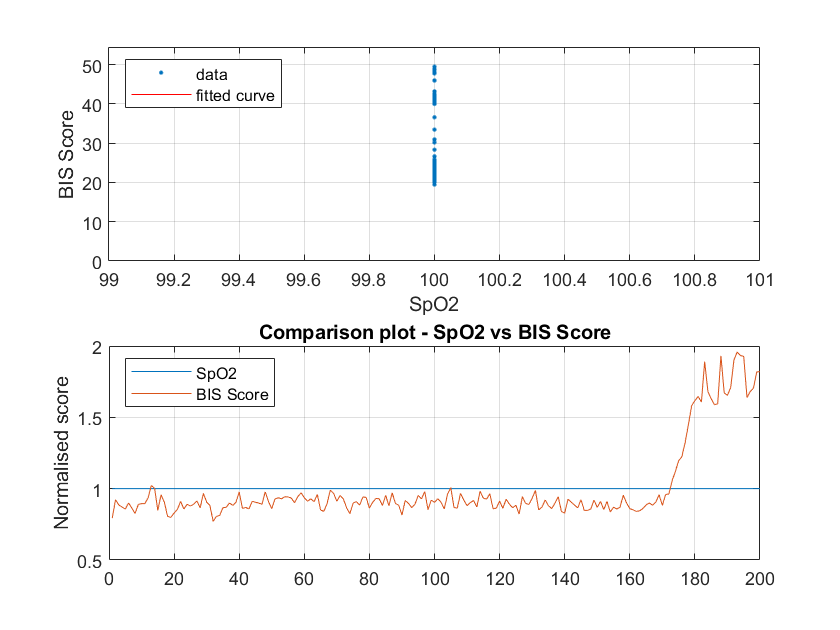

plt =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


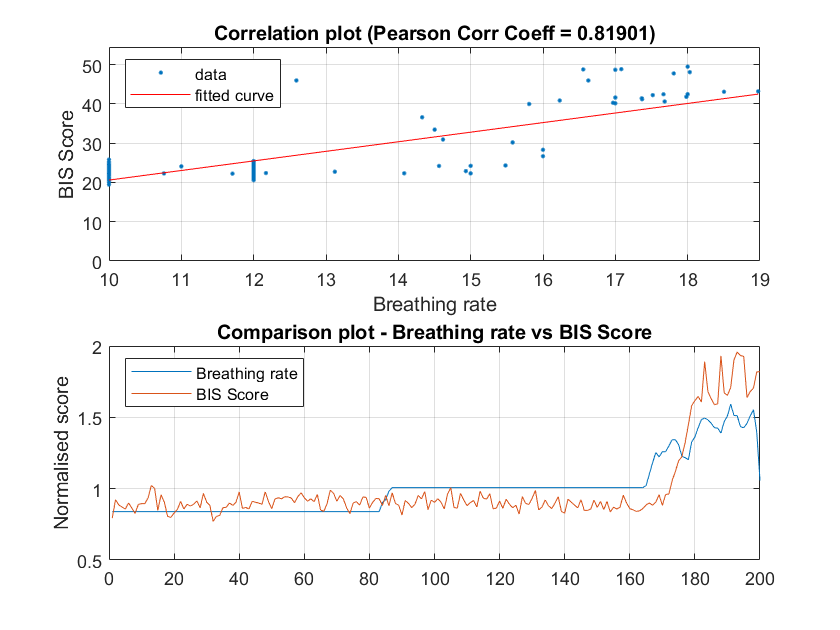

plt =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


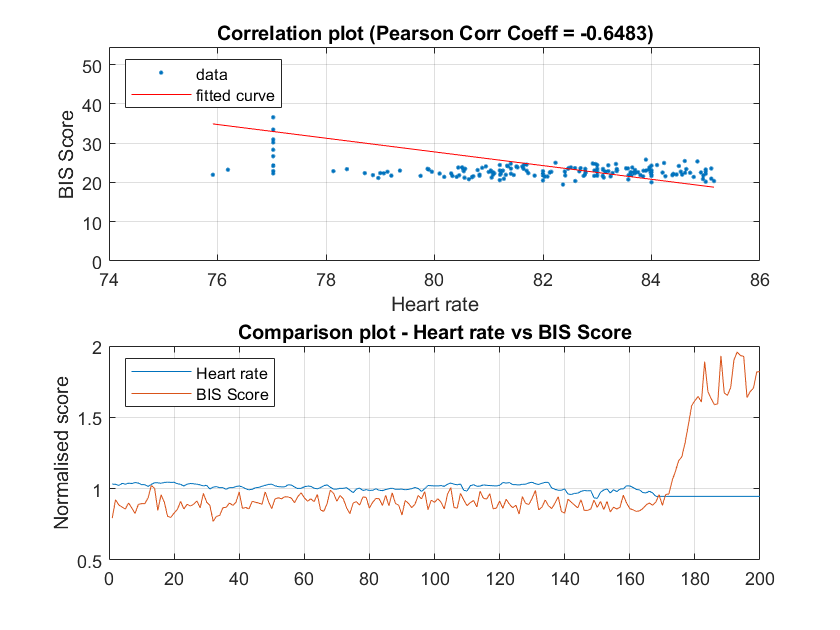

plt =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


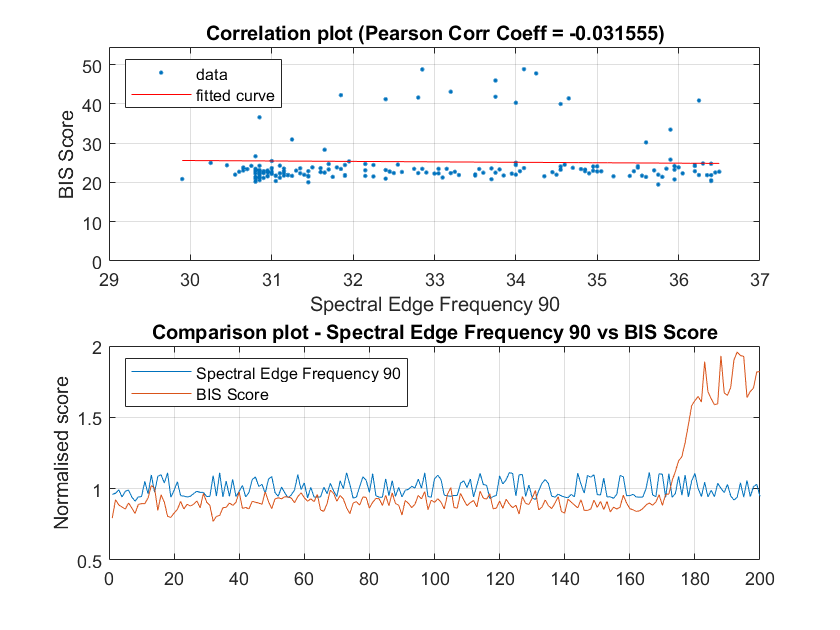

plt =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


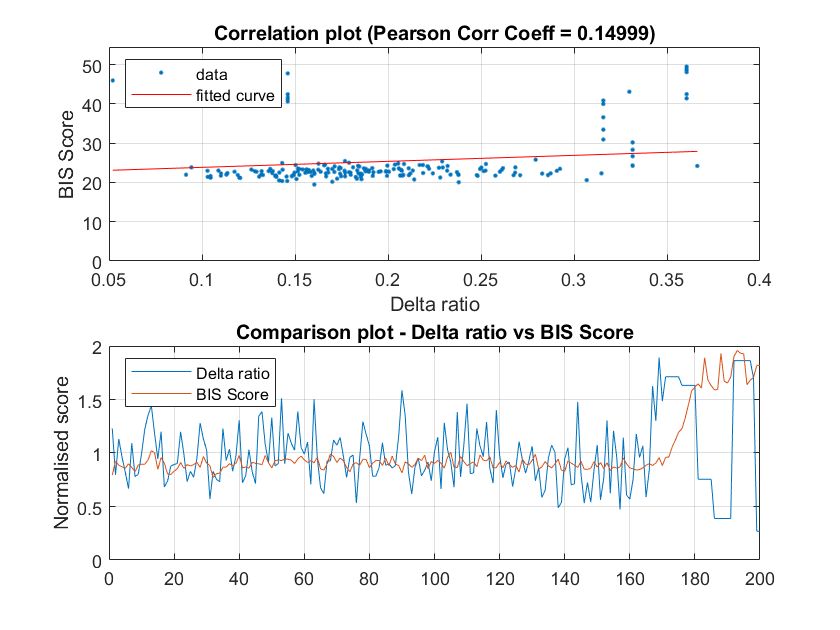

plt =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


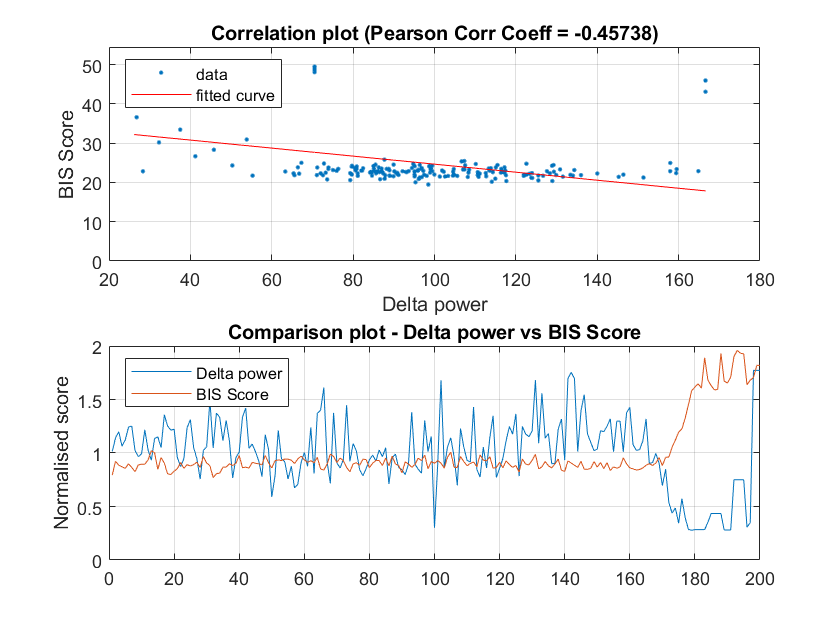

plt =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


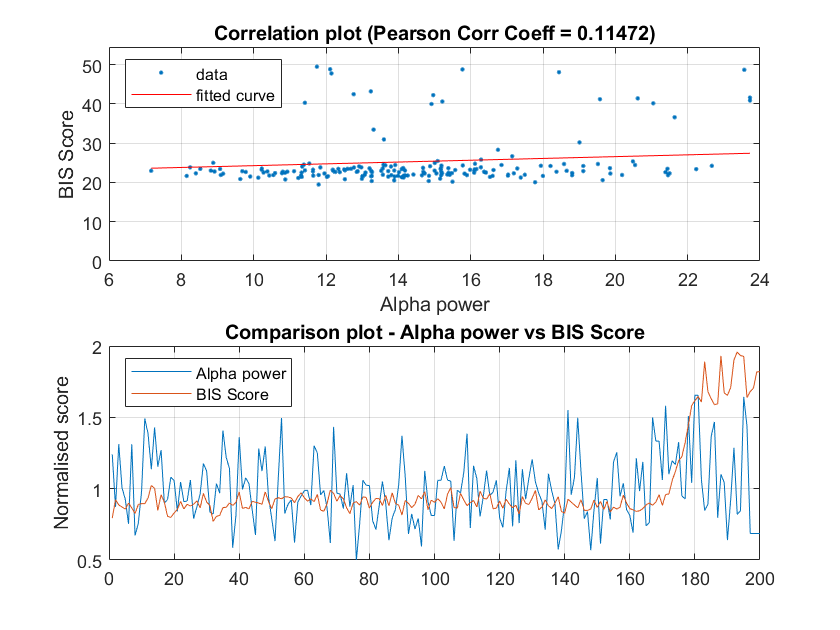

plt =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


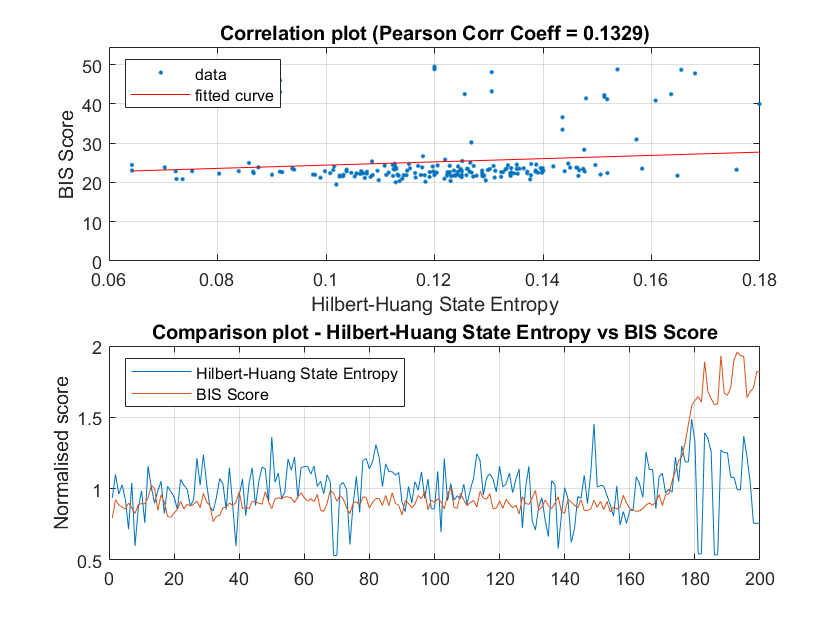

plt =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


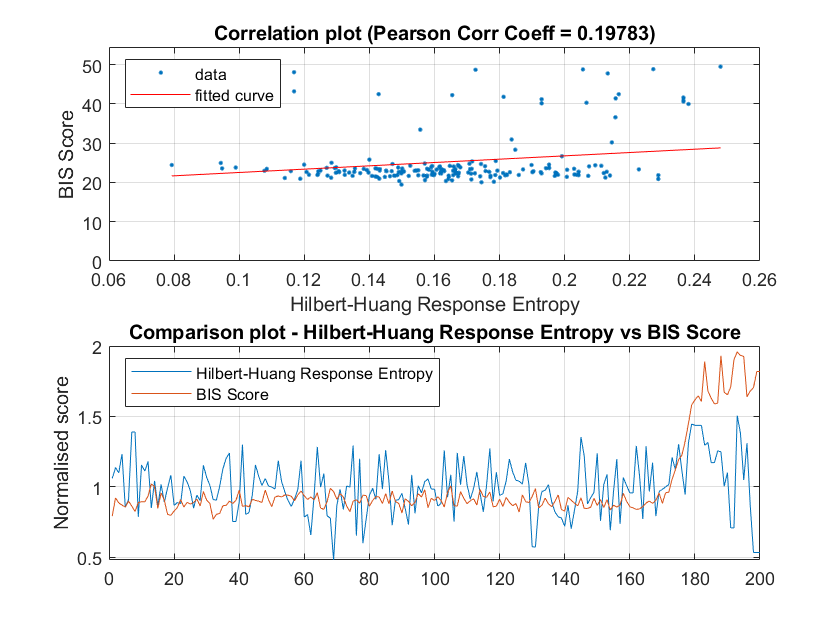

plt =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


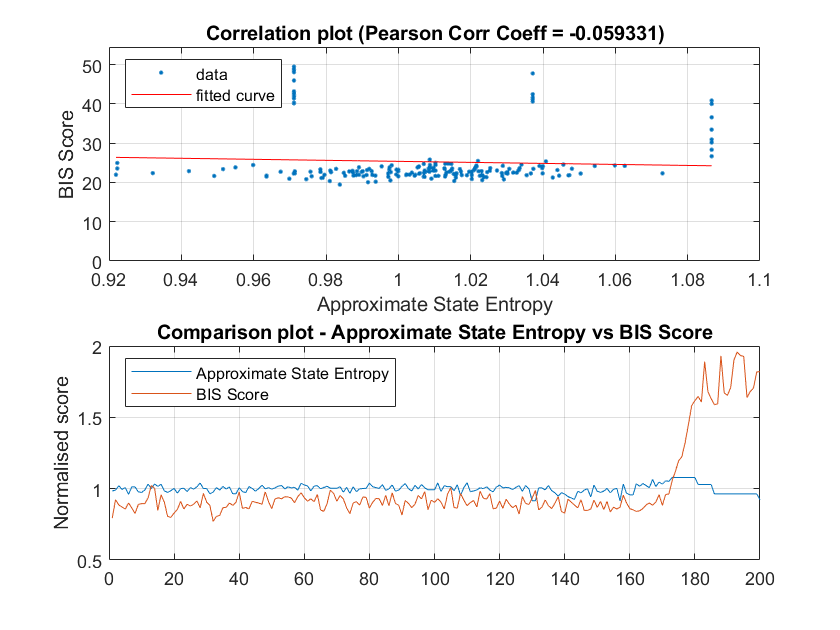

plt =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


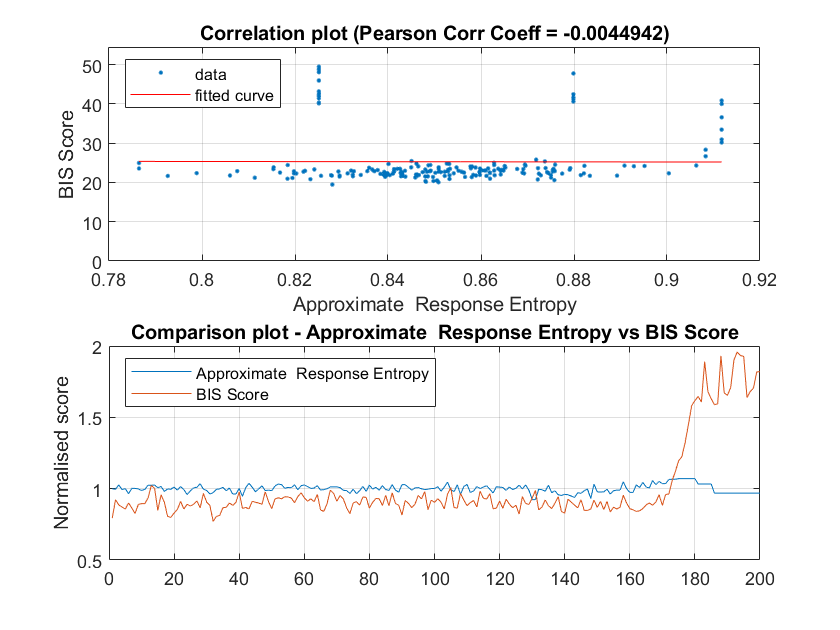

warning off
labels = ["SpO2","Breathing rate","Heart rate","Spectral Edge Frequency 90","Delta ratio","Delta power","Alpha power","Hilbert-Huang State Entropy", "Hilbert-Huang Response Entropy", "Approximate State Entropy", "Approximate  Response Entropy","BIS Score"];
datamatrix_=datamatrix(1050:end,:);
x=1:1:200;
for i=1:11
    datamatrix_(:,i)=filloutliers(datamatrix_(:,i),'previous');
    [f,v]=fit(datamatrix_(:,i),datamatrix_(:,12),'poly1');
    R=corrcoef(datamatrix_(:,i),datamatrix_(:,12));
    figure()
    subplot(2, 1, 1)
    plot(f,datamatrix_(:,i),datamatrix_(:,12),'.')
    ylim([0 max(datamatrix_(:,12))+5])
    ylabel(labels(12))
    xlabel(labels(i))
    legend("Location","northwest")
    title("Correlation plot (Pearson Corr Coeff = "+R(1,2)+")")
    grid on
    subplot(2, 1, 2)
    plot(x,datamatrix_(:,i)./mean(datamatrix_(:,i)))
    hold on
    plot(x,datamatrix_(:,12)./mean(datamatrix_(:,12)))
    hold off
    ylabel("Normalised score")
    %xlabel()
    title("Comparison plot - "+labels(i)+" vs "+labels(12))
    legend(labels(i),labels(12),"Location","northwest")
    grid on
    plt=gcf;
    exportgraphics(plt,"D:\OneDrive - Indian Institute of Science\4th Sem\NSP\NSP-Grant-Proposal\Images\"+labels(i)+".png");
end